# Time evolution for the linear Schrodinger equation on a lollipop graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

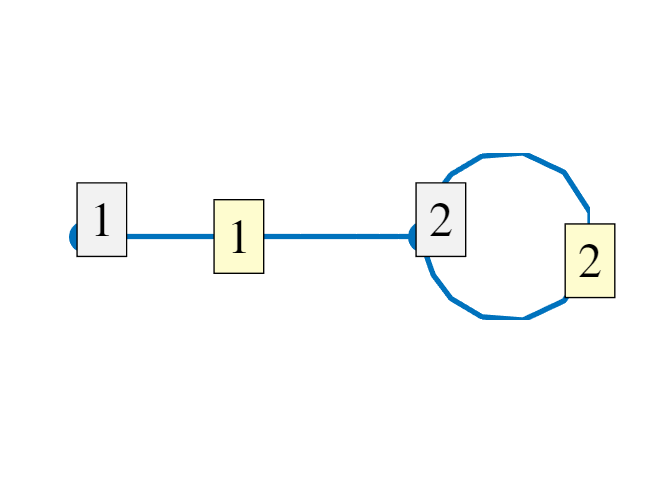

Phi = quantumGraphFromTemplate('multibell','discretization','Chebyshev','nX',16,'nbells',1);
Phi.plot('layout')

## Define the function

We define the linear Schrodinger equation on Phi.

nEdges = length(Phi.L); % Number of edges
nBCs = 2*nEdges;        % Number of BC conditions
[~,~,n] = Phi.nx;       % Number of x points

A = Phi.laplacianMatrix;                    % The second spatial derivative operator
B = Phi.weightMatrix;                       % The rectangular collocation or weight matrix
C = [B(1:(n-nBCs),:); A((n-nBCs+1):n,:)];   % Weight matrix diagonal with boundary data in bottom rows

f = @(t,z) 1i * A*z;

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used an eigenfunction of the stationary problem as an initial condtion.

[evec,eval] = Phi.eigs(8);
lambda1 = eval(3);
lambda2 = eval(5);
u0 = lambda1.*evec(:,3)+lambda2.*evec(:,5);
deltat=1e-04;
tend = 1;
[u,t] = Phi.timeEvolveDAE(f,u0,deltat,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every few data points.

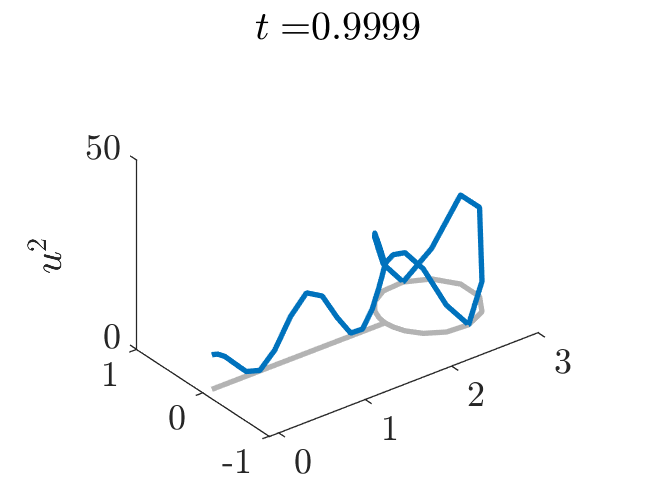

scale = 1/(100*deltat);
for i=1:size(u,2)/scale
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-0.1 3 -1 1 0 50])
    daspect([1 1 25])
    title(['$t=$',num2str(t(scale*i))])
    zlabel('$u^2$')
    pause(.0000000001)
end

## Error Analysis

We use an analytical solution to 

uana = @(t) exp(1i*lambda1*t)*lambda1.*evec(:,3)+exp(1i*lambda2*t)*lambda2.*evec(:,5);

error = zeros(1,size(u,2));
for i=1:size(u,2)/scale
    error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
end

disp('The error is:')

The error is:


disp(abs(max(error)))

   5.1552e-11

